clear
load("data.mat")

% % Constants
% global baseToCoxa;
% global coxaToFemur;
% global femurToTibia;
% global tibiaToEnd;
% global stepLength;
% global thetas;
% baseToCoxa = 140

baseToCoxa = 140

% coxaToFemur = 55

coxaToFemur = 55

% femurToTibia = 135

femurToTibia = 135

% tibiaToEnd = 189

tibiaToEnd = 189

% stepLength = 100

stepLength = 100

% thetas = [0 45 135 180 225 315] % In degrees, Offset for each leg from 1 to 6

thetas =      0    45   135   180   225   315


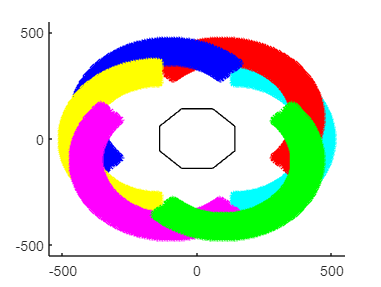

% 
% % Creating Transformation Matrix for each leg
% % T_BaseToCoxaLeg1 = T_BaseToCoxa(thetas(1));
% T_Leg1ToLeg2 = T_leg1Tolegn(thetas(2));
% T_Leg1ToLeg3 = T_leg1Tolegn(thetas(3));
% T_Leg1ToLeg4 = T_leg1Tolegn(thetas(4));
% T_Leg1ToLeg5 = T_leg1Tolegn(thetas(5));
% T_Leg1ToLeg6 = T_leg1Tolegn(thetas(6));
% 
% % Creating array of position vectors for each leg
% numCoordinates = 3800;
% zPosition = -100.14;
% leg1 = createLeg(numCoordinates, zPosition);
% leg2 = createLeg(numCoordinates, zPosition);
% leg3 = createLeg(numCoordinates, zPosition);
% leg4 = createLeg(numCoordinates, zPosition);
% leg5 = createLeg(numCoordinates, zPosition);
% leg6 = createLeg(numCoordinates, zPosition);
% 
% % Creating position vector for the origin/iniitial position of each leg
% o_q1 = deg2rad(108-90);
% o_q2 = deg2rad(24.5-90);
% o_q3 = deg2rad(90-90);
% leg1_origin = [forwardKinematics('x', o_q1, o_q2, o_q3); forwardKinematics('y', o_q1, o_q2, o_q3); zPosition; 1];
% leg2_origin = T_Leg1ToLeg2 * leg1_origin;
% leg3_origin = T_Leg1ToLeg3 * leg1_origin;
% leg4_origin = T_Leg1ToLeg4 * leg1_origin;
% leg5_origin = T_Leg1ToLeg5 * leg1_origin;
% leg6_origin = T_Leg1ToLeg6 * leg1_origin;
% 
% % Defining the hexagon that makes up the base of the robot
% global hexagonx;
% global hexagony;
% hexagonx = [140, 140, 57.99, -57.99, -140, -140, -57.99, 57.99, 140];
% hexagony = [-57.99, 57.99, 140, 140, 57.99, -57.99, -140, -140, -57.99];
% 
% % Iterating through all possible angles and saving those that have correct
% % z position
% i = 0;
% for a3 = 0:180 
%     q3 = deg2rad(a3) - pi / 2;
%     for a1 = 0:180
%         q1 = deg2rad(a1) - pi / 2;
%         for a2 = 0:180
%             q2 = deg2rad(a2) - pi / 2;
%             z = forwardKinematics('z', q1, q2, q3);
%             if (zPosition-0.25 <= z) && (z <= zPosition+0.25)
%                 i = i + 1;
%                 % X & Y respectively
%                 leg1(1, i) = forwardKinematics('x', q1, q2, q3);
%                 leg1(2, i) = forwardKinematics('y', q1, q2, q3);
%                 
%                 leg2(:, i) = T_Leg1ToLeg2 * leg1(:, i);
%                 leg3(:, i) = T_Leg1ToLeg3 * leg1(:, i);
%                 leg4(:, i) = T_Leg1ToLeg4 * leg1(:, i);
%                 leg5(:, i) = T_Leg1ToLeg5 * leg1(:, i);
%                 leg6(:, i) = T_Leg1ToLeg6 * leg1(:, i);
%             end
%         end
%     end
% end
% 
% % Saving the raw data, so that we can run the file without needing to
% % recalculate everything each time
% save("data.mat")


% Graphing all the workspaces together
figure
hold on
plot(hexagonx, hexagony, 'black')
plot(leg1(1, :), leg1(2, :), 'cyan*')
plot(leg2(1, :), leg2(2, :), 'red*')
plot(leg3(1, :), leg3(2, :), 'blue*')
plot(leg4(1, :), leg4(2, :), 'yellow*')
plot(leg5(1, :), leg5(2, :), 'magenta*')
plot(leg6(1, :), leg6(2, :), 'green*')
axis([-550 550 -550 550])
hold off

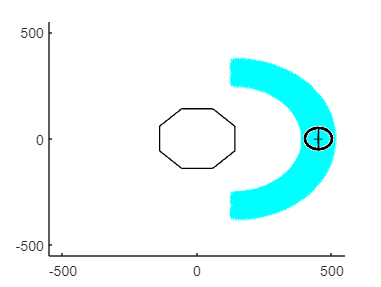


% Workspace graphs for each leg along with step boundary
graphLegWS(leg1, leg1_origin, 'cyan*')

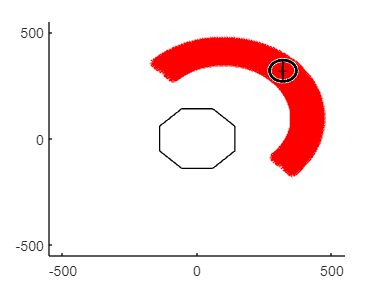

graphLegWS(leg2, leg2_origin, 'red*')

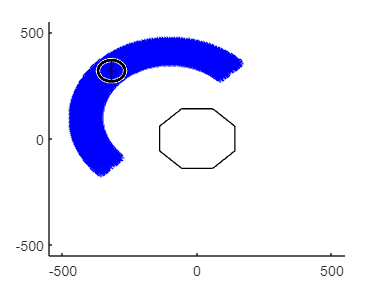

graphLegWS(leg3, leg3_origin, 'blue*')

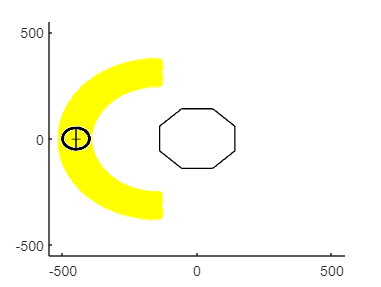

graphLegWS(leg4, leg4_origin, 'yellow*')

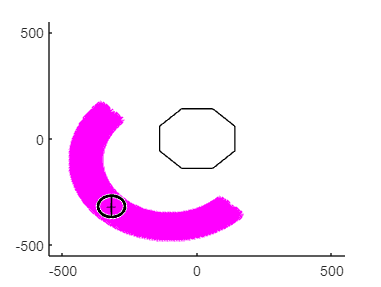

graphLegWS(leg5, leg5_origin, 'magenta*')

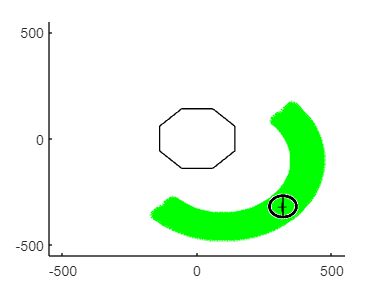

graphLegWS(leg6, leg6_origin, 'green*')

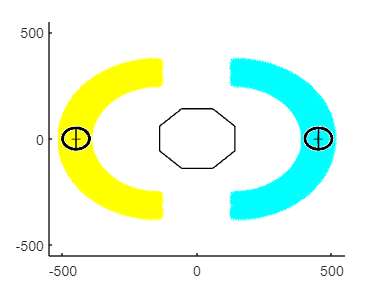


% Workspace graphs for each pair of leg along with step boundary (used
% for portfolio website)
graphtwoLegWS(leg1, leg1_origin, 'cyan*', leg4, leg4_origin, 'yellow*');

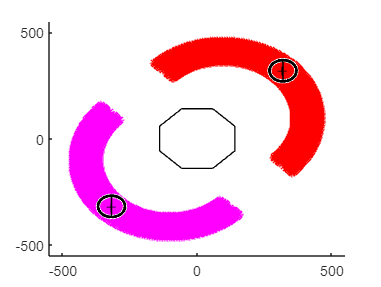

graphtwoLegWS(leg2, leg2_origin, 'red*', leg5, leg5_origin, 'magenta*');

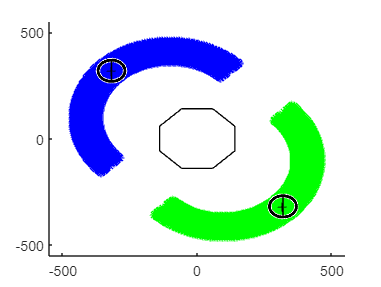

graphtwoLegWS(leg3, leg3_origin, 'blue*', leg6, leg6_origin, 'green*');

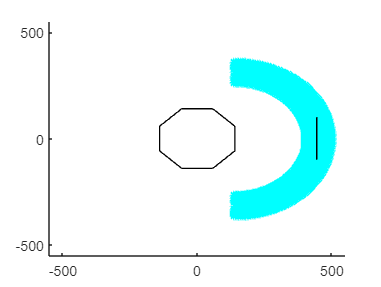


% Showcasing a step length of 200 mm
x1 = 444.63;
y1 = 0;
x2 = 365;
y2 = 245;
dy = 200/2;
figure
hold on
plot(hexagonx, hexagony, 'k')
plot(leg1(1, :), leg1(2, :), 'c*')
plot([x1, x1], [y1-dy, y1+dy], 'k')
axis([-550 550 -550 550])
hold off

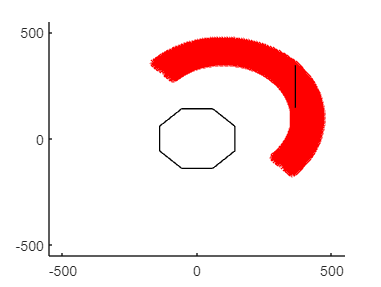

figure
hold on
plot(hexagonx, hexagony, 'k')
plot(leg2(1, :), leg2(2, :), 'r*')
plot([x2, x2], [y2-dy, y2+dy], 'k')
axis([-550 550 -550 550])
hold off


% Calculating the 4 coordinates (for each leg) required to move forward
fwdPathLeg1 = forwardPathCoordinates(stepLength, leg1_origin);
fwdPathLeg2 = forwardPathCoordinates(stepLength, leg2_origin);
fwdPathLeg3 = forwardPathCoordinates(stepLength, leg3_origin);
fwdPathLeg4 = forwardPathCoordinates(stepLength, leg4_origin);
fwdPathLeg5 = forwardPathCoordinates(stepLength, leg5_origin);
fwdPathLeg6 = forwardPathCoordinates(stepLength, leg6_origin);

T = table ;  % create empty table 
fname = 'Coordinates.xls' ;   % Name of excel file
writetable(T,fname) % Make empty Excel file

% Printe the angles required for each position to the console and to the
% excel file
printCoordinates(fwdPathLeg1, 1, fname)

leg 1:


ik =   107.1300   25.1100   90.0000


ik =   105.8400   27.7000   99.1300


ik =   135.9400   13.1700   90.0000


ik =   105.8400   27.7000   80.8700


printCoordinates(fwdPathLeg2, 2, fname)

leg 2:


ik =   107.1300   25.1100   90.0000


ik =    91.3400   55.5300   95.8300


ik =   135.9400   13.1700   90.0000


ik =   116.0100    6.5300   82.6900


printCoordinates(fwdPathLeg3, 3, fname)

leg 3:


ik =   107.1300   25.1100   90.0000


ik =    91.3400   55.5300   84.1700


ik =   135.9400   13.1700   90.0000


ik =   116.0100    6.5300   97.3100


printCoordinates(fwdPathLeg4, 4, fname)

leg 4:


ik =   107.1300   25.1100   90.0000


ik =   105.8400   27.7000   80.8700


ik =   135.9400   13.1700   90.0000


ik =   105.8400   27.7000   99.1300


printCoordinates(fwdPathLeg5, 5, fname)

leg 5:


ik =   107.1300   25.1100   90.0000


ik =   116.0100    6.5300   82.6900


ik =   135.9400   13.1700   90.0000


ik =    91.3400   55.5300   95.8300


printCoordinates(fwdPathLeg6, 6, fname)

leg 6:


ik =   107.1300   25.1100   90.0000


ik =   116.0100    6.5300   97.3100


ik =   135.9400   13.1700   90.0000


ik =    91.3400   55.5300   84.1700


function leg = createLeg(numCoordinates, zPosition) % Creates a 2D array for holding the coordinates of the legs
    leg = zeros(4, numCoordinates);
    leg(4,:) = 1;
    leg(3,:) = zPosition;
end

% Graphs the workspace of each leg along with the step boundary
function graphLegWS(leg, leg_origin, style)
    global stepLength;
    global hexagonx;
    global hexagony;
    
    figure
    hold on
    plot(hexagonx, hexagony, 'black')
    plot(leg(1, :), leg(2, :), style)
    plot(leg_origin(1), leg_origin(2), 'black+')

    center = [leg_origin(1) leg_origin(2)];
    viscircles(center,stepLength/2,'Color','black');
    plot([leg_origin(1), leg_origin(1)], [leg_origin(2)-stepLength/2, leg_origin(2)+stepLength/2], 'black-')
 
    axis([-550 550 -550 550])
    hold off
end

% Graphs the workspace of two legs along with their step boundary
function graphtwoLegWS(firstleg, firstleg_origin, firststyle, secondleg, secondleg_origin, secondstyle)
    global stepLength;
    global hexagonx;
    global hexagony;
    
    figure
    hold on
    plot(hexagonx, hexagony, 'black')
    plot(firstleg(1, :), firstleg(2, :), firststyle)
    plot(firstleg_origin(1), firstleg_origin(2), 'black+')
    
    center = [firstleg_origin(1) firstleg_origin(2)];
    viscircles(center,stepLength/2,'Color','black');
    plot([firstleg_origin(1), firstleg_origin(1)], [firstleg_origin(2)-stepLength/2, firstleg_origin(2)+stepLength/2], 'black-')

    plot(hexagonx, hexagony, 'black')
    plot(secondleg(1, :), secondleg(2, :), secondstyle)
    plot(secondleg_origin(1), secondleg_origin(2), 'black+')

    center = [secondleg_origin(1) secondleg_origin(2)];
    viscircles(center,stepLength/2,'Color','black');
    plot([secondleg_origin(1), secondleg_origin(1)], [secondleg_origin(2)-stepLength/2, secondleg_origin(2)+stepLength/2], 'black-')
 
    axis([-550 550 -550 550])
    hold off
end

% Retrieves the required angles and prints the angles required for each
% coordinate in the path.
function printCoordinates(fwdPath, leg, fname)
    fprintf('leg %i:\n', leg)
    for i = 1:4
        ik = inverseKinematics(fwdPath(1, i), fwdPath(2, i), fwdPath(3, i), leg);
        ik = round(ik, 2, TieBreaker="even")
        writematrix(ik,fname,'WriteMode','append')
    end
end